# 1 The biophysical forward model and linear mixing

We assume that you have MATLAB installed and that you understand the basics of it. This includes the following: starting a MATLAB session, using the command-line, and using the MATLAB-editor.

For the exercises we are going to use MATLAB-code that has been written specifically for this course, as well the MATLAB-based toolbox FieldTrip. The latter has been initiated at the Donders Centre for Cognitive Neuroimaging. The toolbox is under continuous development and contains many state-of-the-art algorithms for the analysis of electrophysiological data. Unlike other popular toolboxes, FieldTrip does not come with a Graphical User Interface (GUI), and thus simply clicking buttons is not sufficient to achieve what comes to your mind. As a consequence, the novice user may experience some difficulties in getting the most out of the toolbox. Fortunately, there is an excellent website that provides a wealth of information. For the exercises in this course, no detailed knowledge about FieldTrip is required. Howver, if you have some time to spare and feel adventurous, there is a large quantity of tutorials online that can be followed. See [https://www.fieldtriptoolbox.org/](https://www.fieldtriptoolbox.org/) for more information.

## 1.1 Getting started: setting up the MATLAB environment

As a first step, you need to install the required toolboxes on your computer. These can be obtained from Brightspace or githib. We advise you to create a separate folder that will contain the material for this course. For example, on Windows, you could create a folder in 'My Documents' called 'neuroimaging2', with a subfolder called 'matlab'. You have to download the two zip-files `fieldtrip.zip` and `ni2.zip` from Brightspace to this folder and unzip them in this location.

Next, MATLAB needs to know where to find the code we are using in the exercises. To this end, the folders you have just created need to be added to the MATLAB-path. Although this can be done through the 'Set Path' option (see figure 1), we will use a `startup.m` file. This is a script that automatically deals with the path-settings that are relevant for the exercises. Each time you start a MATLAB-session, you need to change the Current Folder to `ni2`, and type `ni2_startup` on the command line. This will automatically ensure that the path-settings are correct.

ni2_startup

clearing all variables from the workspace
restoring the default MATLAB-path
adding /Users/roboos/Documents/werk/teaching/cns/2223-neuroimaging2/ni2 to the MATLAB-path
adding /Users/roboos/Documents/werk/teaching/cns/2223-neuroimaging2/fieldtrip to the MATLAB-path
-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------

## 1.2 Getting started: tips on how to approach the exercises

The best way to approach the exercises is to create a MATLAB-script that can be used to copy-and-paste the MATLAB-code in the instructions, and allows you to play around with various parameter settings etc. You can open a new script in the MATLAB-editor by typing edit on the command line, or by going to File->New->Script. Next, you can save each script as a separate file in your course folder.

# 2 Spatial mixing is linear mixing is matrix multiplication

Electrophysiological signals typically represent a mixture of the underlying neuronal sources. The next exercises intend to give some fundamental insights with respect to the general mixing phenomenon. After doing these exercises:

- You will understand that instantaneous mixing is the same as making a linear combination of the underlying 'source' processes.

- You will know that making a weighted combination is equivalent to doing a matrix multiplication.

- Argue that temporal characteristics of the sources and the spatial mixing interact in a non-trivial way.

We start with the generation of some 'source signals'. To this end we can use the function `ni2_activation`. If you type `help ni2_activation` on the MATLAB-command line you can read how to use the function. Let's start with

[sourceactivity, time] = ni2_activation;
whos sourceactivity time

  Name                Size              Bytes  Class     Attributes

  sourceactivity      1x1000             8000  double              
  time                1x1000             8000  double              



Without specifying any input arguments, the function will set all parameters to a default value. Type `help ni2_activation` to see the default parameter values.

The output variables |sourceactivity| and |time| contain for each sampled time point the amplitude of the source signal, and the time in seconds. You can visualize the activity by using MATLAB's built-in function plot. Type

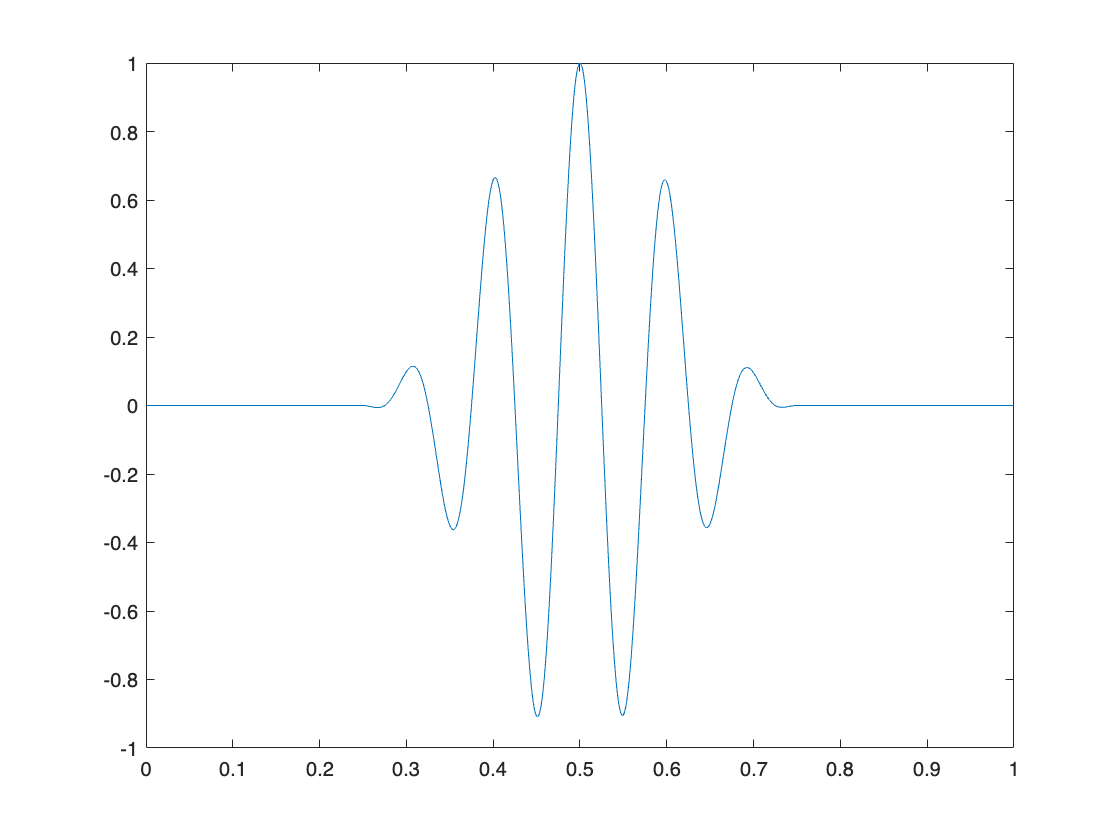

figure; plot(time, sourceactivity);

***Verify whether the default parameter settings in ni2_activation coincide with what is described in the function's.***

Now we will create a second time course that peaks at 0.4 seconds and which has an oscillation frequency of 5 Hz:

[sourceactivity2, time] = ni2_activation('latency', 0.4, 'frequency', 5);

whos sourceactivity2 time

  Name                 Size              Bytes  Class     Attributes

  sourceactivity2      1x1000             8000  double              
  time                 1x1000             8000  double              



Verify the result by using the plot function. You can visualize the two time courses in the same figure by doing:

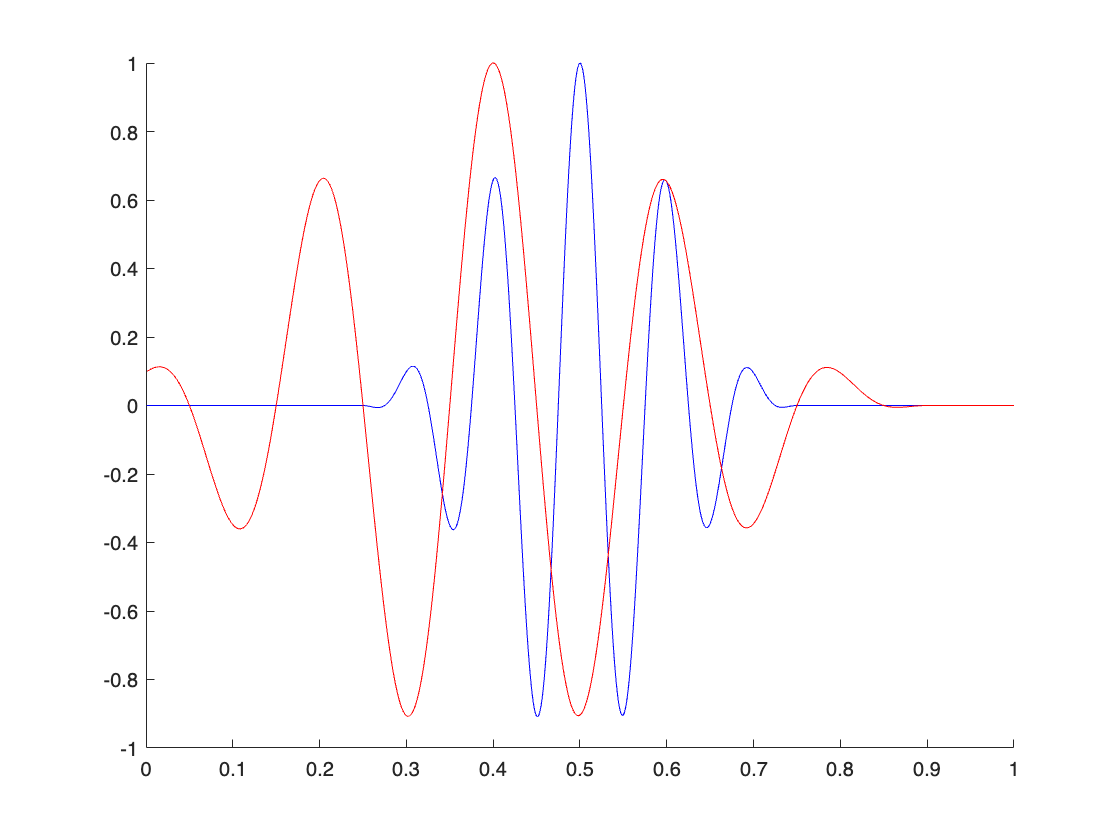

figure; hold on;
plot(time, sourceactivity, 'b');
plot(time, sourceactivity2, 'r');

The `hold on` command is necessary in order to show more than one line in the figure.

***Evaluate the effect of the different parameter settings is on the shape of the time course, by specifying different values for the frequency, ncycle, latency and phase.***

We can apply a very simple instantaneous mixing to the two sources' timecourses by just summing the two. This procedure is equivalent to taking a weighted combination, where the weight for each source is 1:

datamix = sourceactivity + sourceactivity2;
size(datamix)

ans =            1        1000


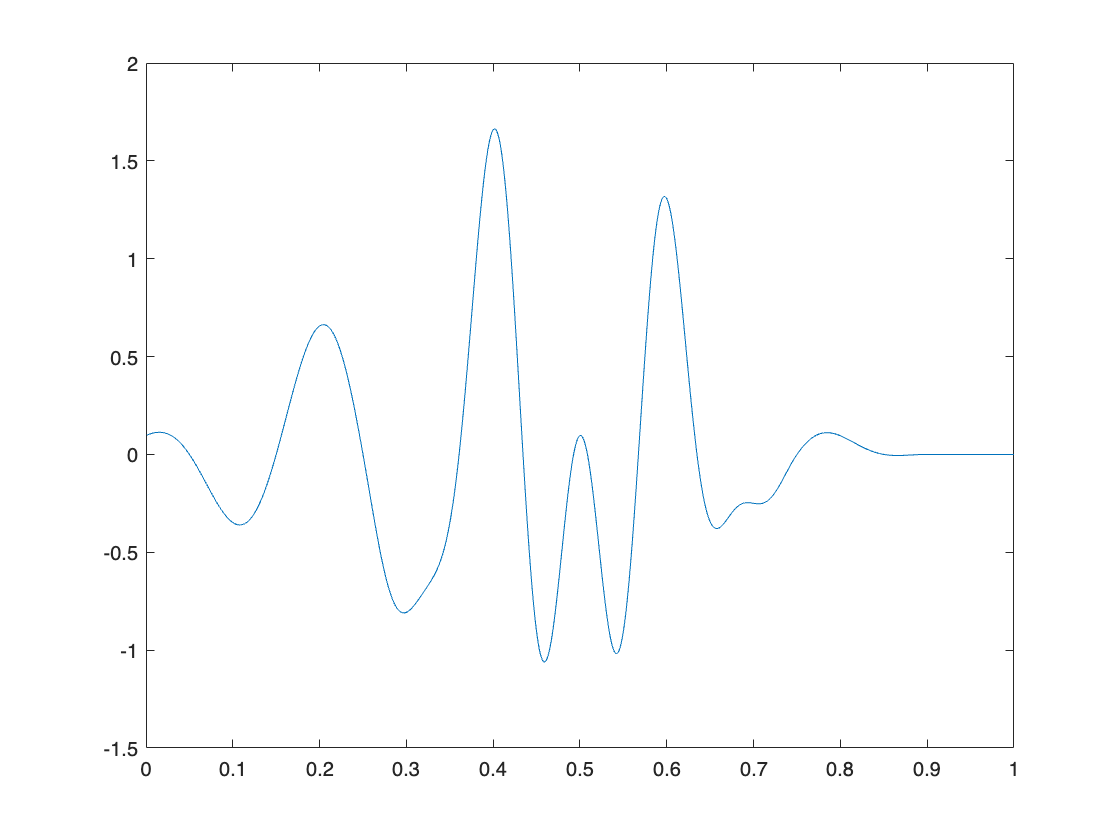

figure; plot(time, datamix);

***Plot the three time courses in a single figure and verify that the peaks and troughs in the mixed signal do not necessarily end up at the same latencies as in the constituent source signals.***

***Investigate how the morphology of the mixed signal changes, when the latency of the second component (sourceactivity2) is changed. Also, see what the effect is of changing the phase of the second component. Hint: create a new `sourceactivity2` with different input parameters to ni2_activation and create a new 'datamix’. Look in the help documentation of ni2_activation to try and understand how to adjust the phase of the signal.***

Next, we will verify that a (weighted) combination of two (or more) activation time courses can be easily achieved by means of a matrix multiplication. To this end we first concatenate the original source activations into a single matrix (each of the original timecourses will be a row in the resulting matrix):

sourcecombined = [sourceactivity; sourceactivity2];
size(sourcecombined)

ans =            2        1000


Note that it is now very easy to plot both timecourses with a single plotting command:

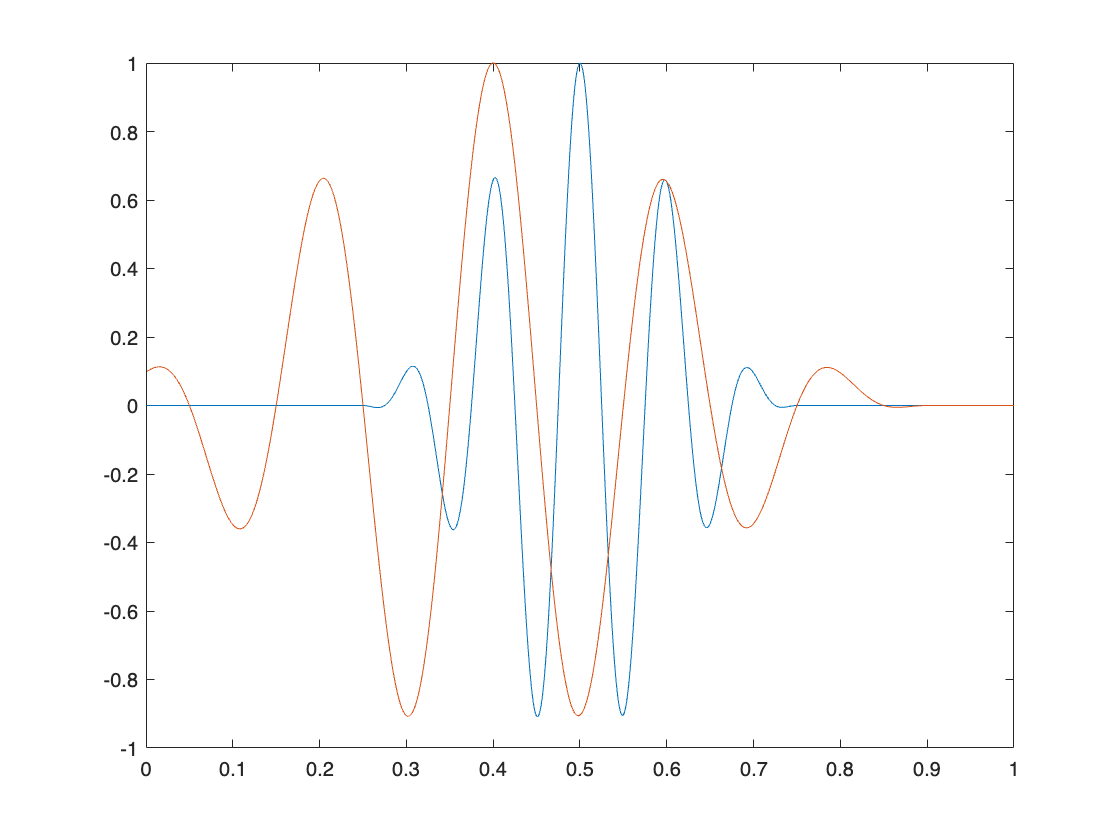

figure
plot(time, sourcecombined);

We can now make a mixture of the two 'sources' with a simple matrix multiplication. Execute the following lines of code and verify that the outcomes are the same.

datamix1 = sourceactivity + sourceactivity2;
datamix2 = sum(sourcecombined, 1);
datamix3 = [1 1] * sourcecombined;

whos datamix1 datamix2 datamix3

  Name          Size              Bytes  Class     Attributes

  datamix1      1x1000             8000  double              
  datamix2      1x1000             8000  double              
  datamix3      1x1000             8000  double              



or, more generally

mix = [1 1];
datamix3 = mix * sourcecombined;

Note that the outcome of a matrix multiplication A*B, where the input matrices are of dimensionality n x m and m x p yields a matrix of dimensionality n x p. If you don't remember exactly the mechanics involved in a matrix multiplication, you should look this up in the course material for the CNS Advanced Mathematics course, or you could check the Wikipedia entry on matrix multiplication. In our example p corresponds with the number of time points, m with the number of 'sources', and n with the number of 'channels'. Our (very simple) 1 x 2 mixing matrix [1 1] thus corresponds to the mapping of 2 sources onto a single channel, where each of the sources is weighted with a factor of 1. We can increase the number of channels by increasing the number of rows in the matrix mix:

mix = [0 1; 0.1 0.9; 0.25 0.75; 0.5 0.5; 0.75 0.25; 0.9 0.1; 1 0];
datamix = mix * sourcecombined;
whos datamix

  Name         Size              Bytes  Class     Attributes

  datamix      7x1000            56000  double              



To better evaluate the individual time courses of the mixed sources, but still visualizing them in the same figure, you can type:

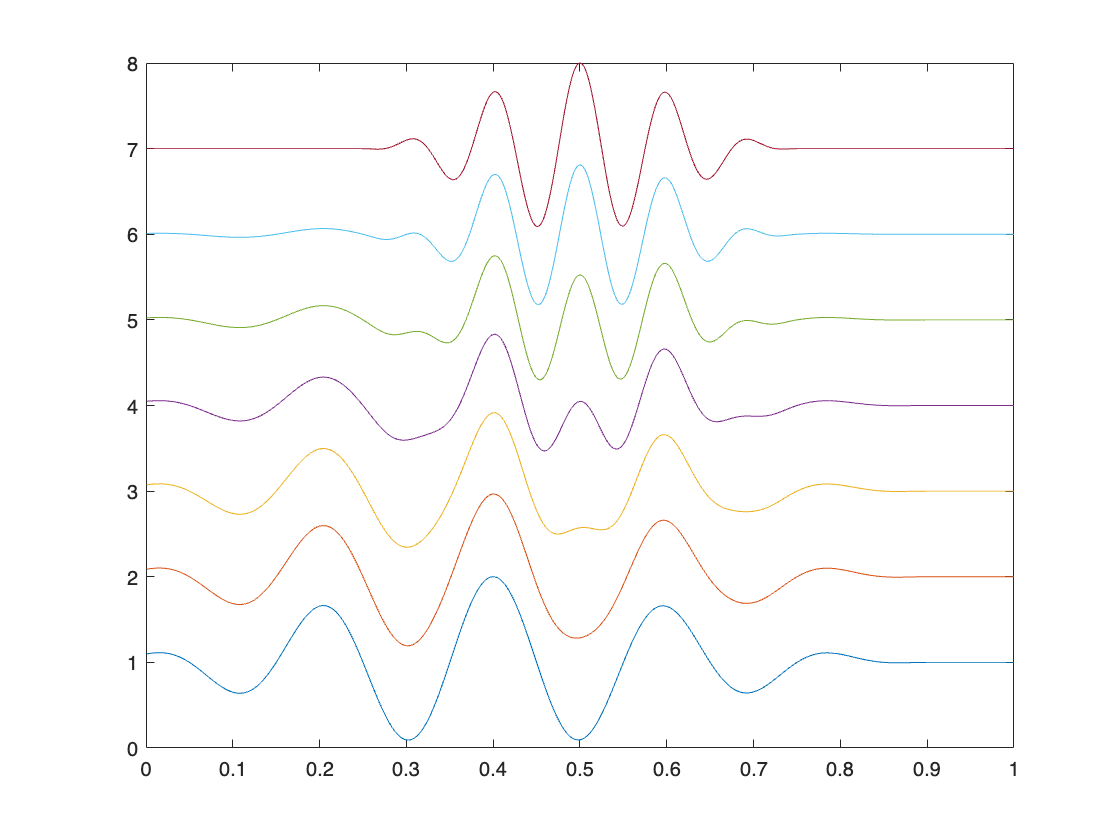

figure; plot(time, datamix+repmat((1:7)', [1 1000]));

The part `repmat((1:7)', [1 1000]))` lifts the signals to different heights. To better see what the repmat function does, type:

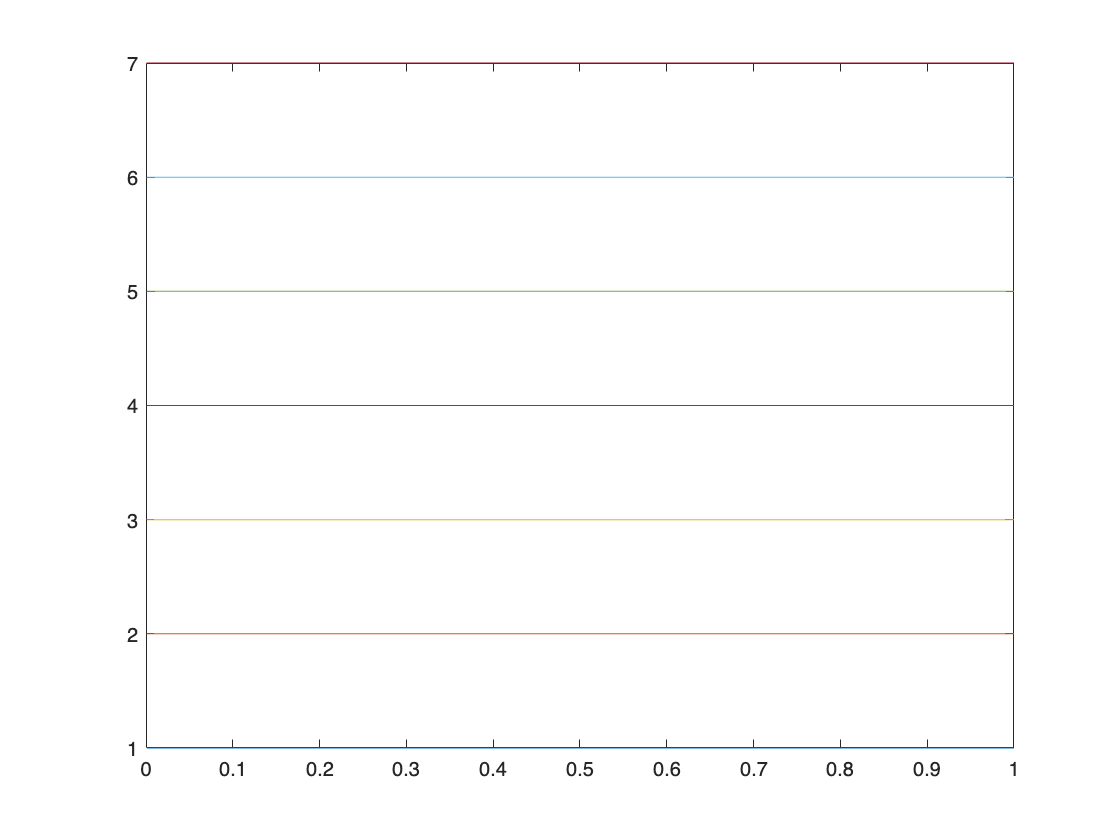

figure; plot(time, repmat((1:7)', [1 1000]));

Note, that the sum of the values in the rows of the mixing matrix do not have to sum to a value of one. Note, also, that the values in the mixing matrix can be negative.

***What is the effect of a negative mixing weight on the mixed result?***

# 3 Spatial mixing of neural sources: the leadfield

This section deals with the spatial topographies of activity that are observed with EEG when neural sources are active. Modeling these spatial topographies when the underlying sources are known is called forward modeling. After doing these exercises

- You will understand the concept of a leadfield.

- You understand the effect of source parameters on the observed topographies.

To build a forward model one needs a model of the sources, a volume conduction model, and information about the sensor array (we will come back to this somewhat later in this course). Sources are typically modeled as equivalent current dipoles (ECDs). At the spatial scale of EEG/MEG an ECD can be represented as a point source with 6 parameters: 3 location parameters (x, y, z coordinates in a (Cartesian) coordinate system), and 3 parameter dipole moment (combining amplitude and orientation information) along the x, y, z-axes of the coordinate system (see figure).

As a volume conduction model we will initially use a simple model, consisting of three concentric spheres. These spheres represent the inner and outer surfaces of the skull, and the scalp surface. In an EEG volume conduction model, these surfaces represent the locations at which the conductivity of the tissue changes rapidly, leading to distortion and smearing of the volume currents. We will use an EEG sensor-array that has 91 electrodes placed on the spherical scalp surface. As such this sensor-array does not correspond to what you typically encounter in real life EEG-setups, but this is not a problem for bringing across the main message.

To create the headmodel, type:

headmodel = ni2_headmodel('type', 'spherical', 'nshell', 3)

headmodel = struct with fields:
       o: [0 0 0]
       r: [8.8000 9.2000 10]
    unit: 'cm'
    type: 'concentricspheres'
    cond: [1 0.0125 1]

To create the sensor array, type:

sensors = ni2_sensors('type', 'eeg')

sensors = struct with fields:
     chanpos: [91×3 double]
    chantype: {91×1 cell}
    chanunit: {91×1 cell}
    coordsys: 'neuromag'
     elecpos: [91×3 double]
       label: {91×1 cell}
        unit: 'cm'

These can be visualized using a few functions from the FieldTrip-toolbox:

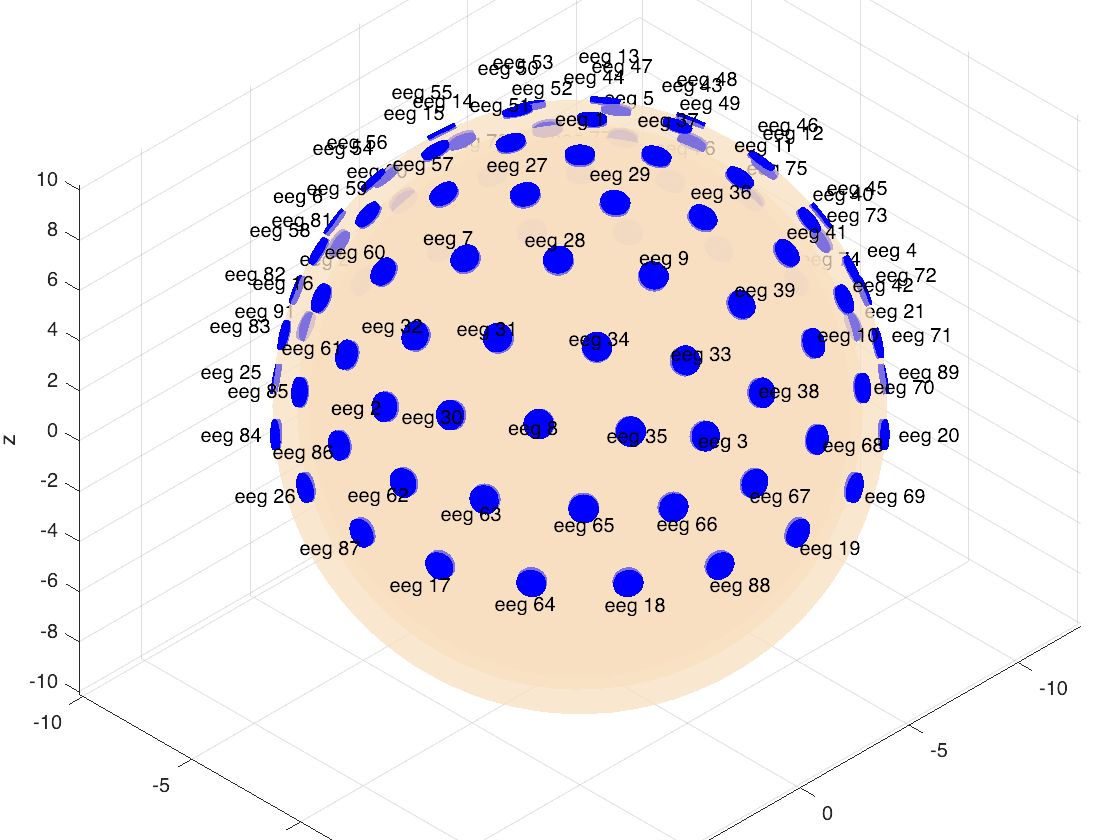

figure; hold on;
ft_plot_headmodel(headmodel, 'edgecolor', 'none', 'facecolor', 'skin'); alpha 0.5 
ft_plot_sens(sensors, 'elecshape', 'disc', 'elecsize', 1, 'label', 'on');
view([1 1 1])
axis on; grid on
xlabel('x'); ylabel('y'); zlabel('z'); 

Now that we have a sensor array and a volume conductor model of the head, we can build a model for any source specified within the volume conductor. For example:

dippar1 = [0 0 6 1 0 0];
leadfield1 = ni2_leadfield(sensors, headmodel, dippar1);

using electrodes specified in the configuration
creating sourcemodel based on user specified dipole positions
using electrodes specified in the configuration
1 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 0 MB
computing leadfield
computing leadfield 1/1

the call to "ft_prepare_leadfield" took 0 seconds and required the additional allocation of an estimated 0 MB


creating layout from cfg.elec
creating layout for eeg system
the call to "ft_prepare_layout" took 2 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotER" took 0 seconds and required the additional allocation of an estimated 0 MB


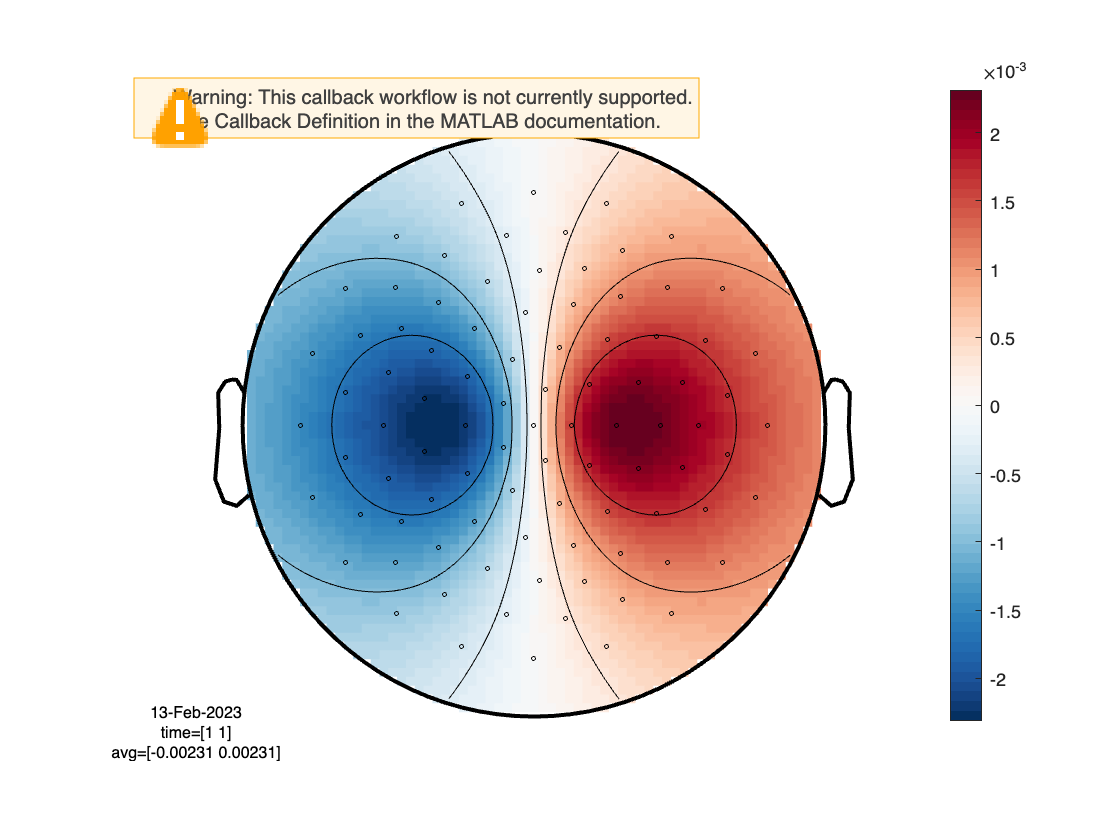

ni2_topoplot(sensors, leadfield1); colorbar

The variable dippar1 consists of 6 elements, where the first triplet of numbers represents the x, y, z-position of the dipole, and the second triplet of numbers represents the dipole moment.

***Take a few moments to try and understand the topography.***

A basic feature of a leadfield is that a change in the amplitude of the dipole does not change the distribution of the peaks in the topography. This can be explored as follows:

dippar2 = [0 0 6 2 0 0];
leadfield2 = ni2_leadfield(sensors, headmodel, dippar2);

using electrodes specified in the configuration
creating sourcemodel based on user specified dipole positions
using electrodes specified in the configuration
1 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 0 MB
computing leadfield
computing leadfield 1/1

the call to "ft_prepare_leadfield" took 0 seconds and required the additional allocation of an estimated 2 MB


creating layout from cfg.elec
creating layout for eeg system
the call to "ft_prepare_layout" took 2 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotER" took 0 seconds and required the additional allocation of an estimated 0 MB


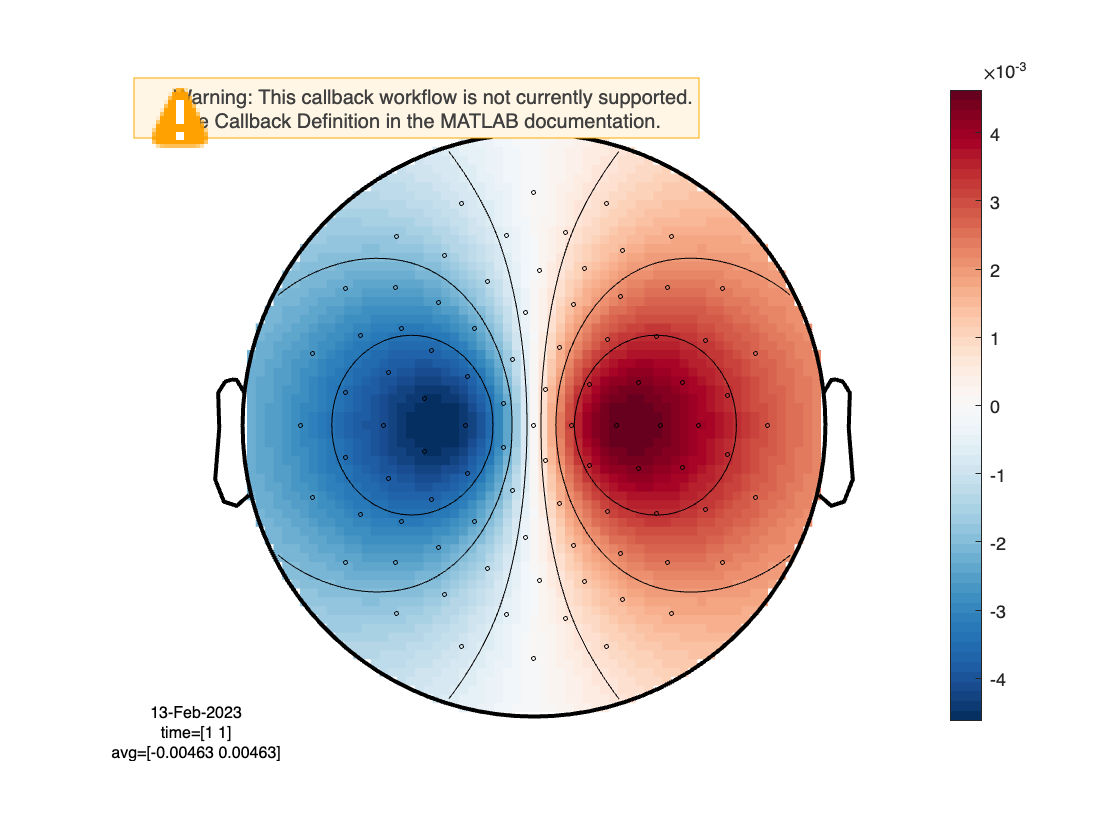

ni2_topoplot(sensors, leadfield2); colorbar

***Verify that the values in leadfield2 differ from the values in leadfield1 by a factor of 2.***

The important consequence of this is that the amplitude can be 'uncoupled' from the orientation (and location) information. Namely:

creating layout from cfg.elec
creating layout for eeg system
the call to "ft_prepare_layout" took 2 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotER" took 0 seconds and required the additional allocation of an estimated 0 MB


ni2_topoplot(sensors, leadfield1*2); colorbar

will yield the same result as:

creating layout from cfg.elec
creating layout for eeg system
the call to "ft_prepare_layout" took 2 seconds and required the additional allocation of an estimated 7 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotER" took 0 seconds and required the additional allocation of an estimated 0 MB


ni2_topoplot(sensors, leadfield2); colorbar

For this reason, it is custom (and convenient) that leadfields are defined as the spatial topography of the electric potential (EEG) or magnetic field (MEG) due to a unit-amplitude source at a given location and orientation.

In the example above the amplitude information (the value '2') just represented the activity of a source in a single time point. The amplitude term can be very easily extended to contain multiple time points, i.e., to become a vector. Mathematically, this can still be expressed as a matrix multiplication:

*leadfield x amplitude time course*

We will return to this very important property in the next section.

Another basic feature is that if two (or more sources) are simultaneously active, the topographies caused by the individual sources' mix linearly to yield a composite topography:

dippar3 = [0 3 6 0 1 0; 0 -3 6 1 0 0];
leadfield3 = ni2_leadfield(sensors, headmodel, dippar3);

using electrodes specified in the configuration
creating sourcemodel based on user specified dipole positions
using electrodes specified in the configuration
2 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 0 MB
computing leadfield
computing leadfield 2/2

the call to "ft_prepare_leadfield" took 0 seconds and required the additional allocation of an estimated 0 MB


creating layout from cfg.elec
creating layout for eeg system
the call to "ft_prepare_layout" took 2 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotER" took 0 seconds and required the additional allocation of an estimated 0 MB


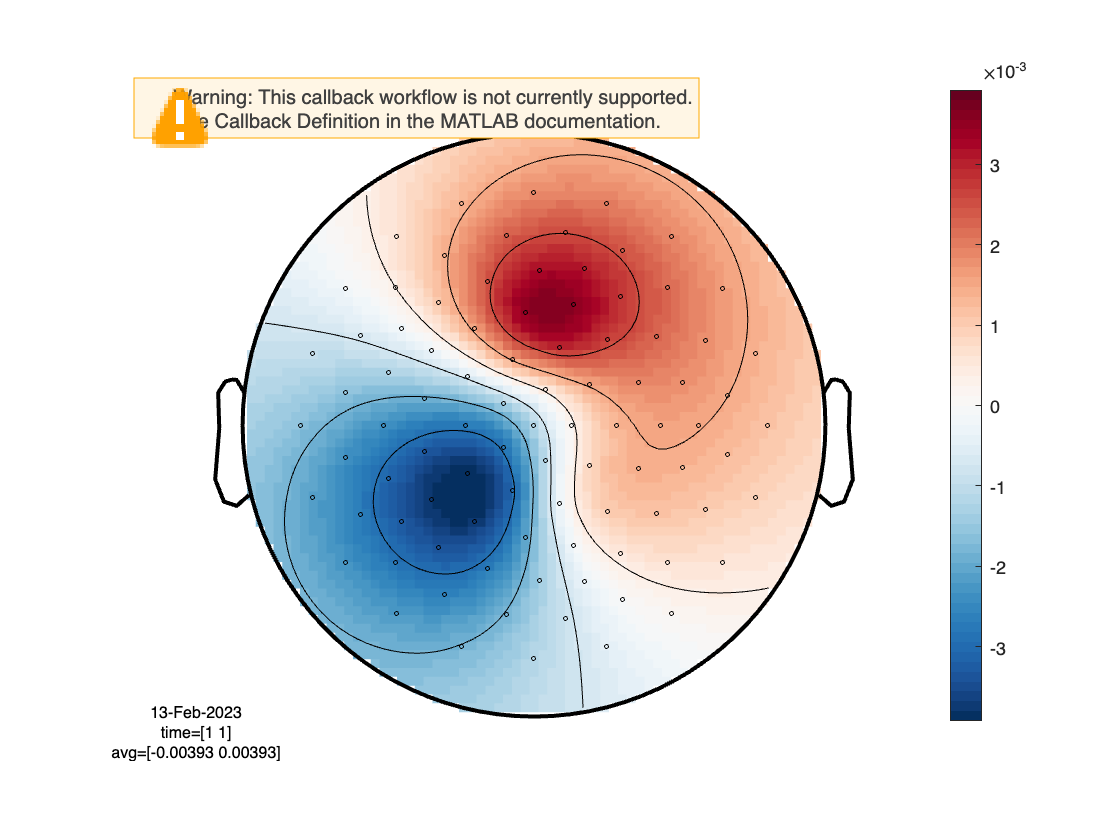

topo = leadfield3*[1; 1];
ni2_topoplot(sensors, topo); colorbar

The variable *dippar3* consists of 2 rows of 6 parameters, each representing a dipole. As a result, the variable leadfield3 consists of two columns, each representing the spatial topography that is caused by one dipole.

Note that the mixing column vector ([1; 1]) features on the right side of the leadfield matrix, as opposed to on the left side (where in addition the mixing vector was a row vector) when we were mixing activation time courses in the previous section. Note also, that in the above example two unit-amplitude sources are located very close to one another. 

***Verify that the topography due to 2 very closely spaced sources (with the same orientation) is hardly distinguishable from a situation where only one source (with twice the single sources’ amplitude) is present at the average location of the two sources.***

This is a very important feature of electromagnetic forward models and in essence the cause for the fact that the inverse problem is ill-posed: there is no unique solution. We will revisit this issue in more detail at a later stage.

So far, we have considered the leadfield of a source located at [0 0 6], with an orientation of [1 0 0]. 

***Explore the effect of changing the position and orientation parameters. Investigate the following situations:***

- ***Keep the orientation fixed and change the location of the source, e.g., by moving it closer to the center of the 'head’.***

- ***Change the y and z position of the source, keeping x the same.***

- ***Keep the location at a fixed position and change the orientation of the source. Start by investigating the orientations [1 0 0], [0 1 0], and [0 0 1].***

- ***Also explore source orientations that have more than 1 non-zero value, e.g. [0 1 1].***

- ***Compare the effect of a change in the sign of the orientation, e.g. [0 1 1] versus [0 -1 -1].***

Up to this point we have explicitly added the orientation parameters when computing a leadfield. Typically, however, a leadfield is defined as a 3-column matrix, where, for a source at a given location, each of the columns represent a unit source with the orientation along the axes of the coordinate system. In other words, the first column represents a source with orientation [1 0 0], the second column represents a source with orientation [0 1 0], etc. Based on this 3-column representation, any orientation of the source can be represented by means of (could it be any different?) linear mixing.

***Verify this.***